# Hobbing - Entwicklung der Mathematik

## Definition

### Parametrierung der Transformationsmatrizen

#### TM der Maschine

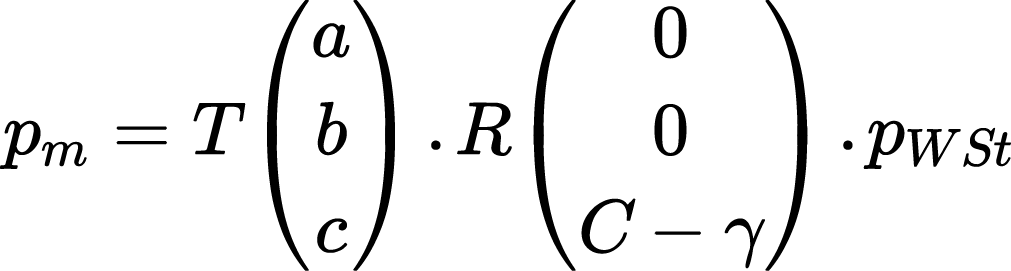

Versatz Achsen zu Null C

syms a b c

Winkel C

syms C

Gamma (Bedeutung?)

syms ga

#### TM Werkzeugkoordinatensystem

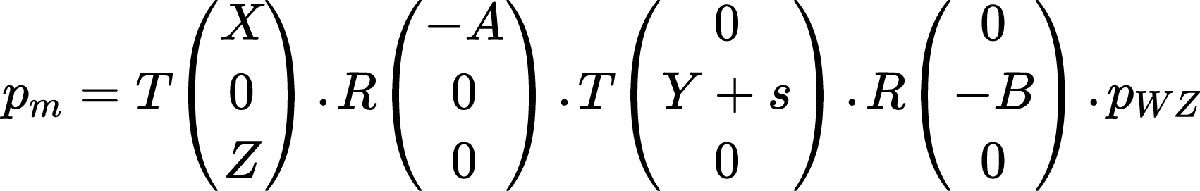

syms X Y Y_shift Z A B

### Koordinaten

Werkzeugkoordinaten, kartesisch:

syms x_WZ y_WZ z_WZ
WZ_kart = dim4([x_WZ;y_WZ;z_WZ],1,'forward')

$$WZ\_kart = \left(\begin{array}{c} x_{\mathrm{WZ}}\\ y_{\mathrm{WZ}}\\ z_{\mathrm{WZ}}\\ 1 \end{array}\right)$$

Werkzeugkoordinaten, Zylinderkoordinaten?

syms r_WZ phi_WZ h_WZ
WZ_zyl = dim4([r_WZ*cos(phi_WZ); h_WZ; r_WZ*sin(phi_WZ)],1,'forward')

$$WZ\_zyl = \left(\begin{array}{c} r_{\mathrm{WZ}}\,\cos\left(\varphi_{\mathrm{WZ}}\right)\\ h_{\mathrm{WZ}}\\ r_{\mathrm{WZ}}\,\sin\left(\varphi_{\mathrm{WZ}}\right)\\ 1 \end{array}\right)$$

### Vorschübe?

syms fZ_WZrad fY_WZrad fX_WZrad f_WSTrad

gesuchter z-Wert

syms z_soll

angle C is function of Werkstück rotation and angle B?

C = f_WSTrad * B

$$C = B\,f_{\mathrm{WSTrad}}$$

## Transformationsmatrizen

### Rotationen

#### B-Achse

Rotation um B-Achse ist um Koordinatensystem y-Achse

R_B = axang2rtm('y',-B)

$$R\_B = \left(\begin{array}{cccc} \cos\left(B\right) & 0 & -\sin\left(B\right) & 0\\ 0 & 1 & 0 & 0\\ \sin\left(B\right) & 0 & \cos\left(B\right) & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Validierung:

R_B_val = [cos(-B) 0 sin(-B) 0; 0 1 0 0; -sin(-B) 0 cos(-B) 0; 0 0 0 1]

$$R\_B\_val = \left(\begin{array}{cccc} \cos\left(B\right) & 0 & -\sin\left(B\right) & 0\\ 0 & 1 & 0 & 0\\ \sin\left(B\right) & 0 & \cos\left(B\right) & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

#### A-Achse

Rotation um A-Achse ist um Koordinatensystem x-Achse

R_A = axang2rtm('x',A)

$$R\_A = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & \cos\left(A\right) & -\sin\left(A\right) & 0\\ 0 & \sin\left(A\right) & \cos\left(A\right) & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Validierung:

R_A_val =   [1 0 0 0; 0 cos(A) -sin(A) 0; 0 sin(A) cos(A) 0; 0 0 0 1]

$$R\_A\_val = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & \cos\left(A\right) & -\sin\left(A\right) & 0\\ 0 & \sin\left(A\right) & \cos\left(A\right) & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

#### C-Achse

Rotation um C-Achse ist um Koordinatensystem z-Achse

R_Cga = axang2rtm('z',-C+ga)

$$R\_Cga = \left(\begin{array}{cccc} \cos\left(\mathrm{ga}-B\,f_{\mathrm{WSTrad}}\right) & -\sin\left(\mathrm{ga}-B\,f_{\mathrm{WSTrad}}\right) & 0 & 0\\ \sin\left(\mathrm{ga}-B\,f_{\mathrm{WSTrad}}\right) & \cos\left(\mathrm{ga}-B\,f_{\mathrm{WSTrad}}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Validierung:

R_Cga_val = [cos(-C+ga) -sin(-C+ga) 0 0; sin(-C+ga) cos(-C+ga) 0 0; 0 0 1 0; 0 0 0 1]

$$R\_Cga = \left(\begin{array}{cccc} \cos\left(\mathrm{ga}-B\,f_{\mathrm{WSTrad}}\right) & -\sin\left(\mathrm{ga}-B\,f_{\mathrm{WSTrad}}\right) & 0 & 0\\ \sin\left(\mathrm{ga}-B\,f_{\mathrm{WSTrad}}\right) & \cos\left(\mathrm{ga}-B\,f_{\mathrm{WSTrad}}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

### Translationen

T_Ys=  [1 0 0 0; 0 1 0 Y+fY_WZrad*B+Y_shift; 0 0 1 0; 0 0 0 1]

$$T\_Ys = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & Y+Y_{\mathrm{shift}}+B\,{\mathrm{fY}}_{\mathrm{WZrad}}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_XZ=  [1 0 0 X+fX_WZrad*B-a; 0 1 0 -b; 0 0 1 Z+fZ_WZrad*B-c; 0 0 0 1]

$$T\_XZ = \left(\begin{array}{cccc} 1 & 0 & 0 & X-a+B\,{\mathrm{fX}}_{\mathrm{WZrad}}\\ 0 & 1 & 0 & -b\\ 0 & 0 & 1 & Z-c+B\,{\mathrm{fZ}}_{\mathrm{WZrad}}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

### Gesamt

Gesamt= R_Cga * T_XZ * R_A * T_Ys * R_B

$$Gesamt = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{2}\,\cos\left(B\right)+\sigma_{1}\,\sin\left(A\right)\,\sin\left(B\right) & -\sigma_{1}\,\cos\left(A\right) & \sigma_{1}\,\cos\left(B\right)\,\sin\left(A\right)-\sigma_{2}\,\sin\left(B\right) & b\,\sigma_{1}+\sigma_{2}\,\sigma_{4}-\sigma_{1}\,\cos\left(A\right)\,\sigma_{3}\\ \sigma_{1}\,\cos\left(B\right)-\sigma_{2}\,\sin\left(A\right)\,\sin\left(B\right) & \sigma_{2}\,\cos\left(A\right) & -\sigma_{1}\,\sin\left(B\right)-\sigma_{2}\,\cos\left(B\right)\,\sin\left(A\right) & \sigma_{1}\,\sigma_{4}-b\,\sigma_{2}+\sigma_{2}\,\cos\left(A\right)\,\sigma_{3}\\ \cos\left(A\right)\,\sin\left(B\right) & \sin\left(A\right) & \cos\left(A\right)\,\cos\left(B\right) & Z-c+B\,{\mathrm{fZ}}_{\mathrm{WZrad}}+\sin\left(A\right)\,\sigma_{3}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\mathrm{ga}-B\,f_{\mathrm{WSTrad}}\right)\\ \sigma_{2}=\cos\left(\mathrm{ga}-B\,f_{\mathrm{WSTrad}}\right)\\ \sigma_{3}=Y+Y_{\mathrm{shift}}+B\,{\mathrm{fY}}_{\mathrm{WZrad}}\\ \sigma_{4}=X-a+B\,{\mathrm{fX}}_{\mathrm{WZrad}} \end{array}$$

auskommentierte TM zum Vergleich

%[ cos(ga - B*f_WSTrad)*cos(B) + sin(ga - B*f_WSTrad)*sin(A)*sin(B), -sin(ga - B*f_WSTrad)*cos(A),   sin(ga - B*f_WSTrad)*cos(B)*sin(A) - cos(ga - B*f_WSTrad)*sin(B), b*sin(ga - B*f_WSTrad) + cos(ga - B*f_WSTrad)*(X - a + B*fX_WZrad) - sin(ga - B*f_WSTrad)*cos(A)*(Y + Y_shift + B*fY_WZrad)]
%[ sin(ga - B*f_WSTrad)*cos(B) - cos(ga - B*f_WSTrad)*sin(A)*sin(B),  cos(ga - B*f_WSTrad)*cos(A), - sin(ga - B*f_WSTrad)*sin(B) - cos(ga - B*f_WSTrad)*cos(B)*sin(A), sin(ga - B*f_WSTrad)*(X - a + B*fX_WZrad) - b*cos(ga - B*f_WSTrad) + cos(ga - B*f_WSTrad)*cos(A)*(Y + Y_shift + B*fY_WZrad)]
%[                                                    cos(A)*sin(B),                       sin(A),                                                      cos(A)*cos(B),                                                                      Z - c + B*fZ_WZrad + sin(A)*(Y + Y_shift + B*fY_WZrad)]
%[                                                                0,                            0,                                                                  0,                                                                                                                           1]

## Anwendung der Transformationsmatrizen

### Gesamt mal Werkzeugkoordinaten

p_WST = Gesamt * WZ_kart;
p_WST(3)

$$ans = Z-c+B\,{\mathrm{fZ}}_{\mathrm{WZrad}}+\sin\left(A\right)\,\left(Y+Y_{\mathrm{shift}}+B\,{\mathrm{fY}}_{\mathrm{WZrad}}\right)+y_{\mathrm{WZ}}\,\sin\left(A\right)+z_{\mathrm{WZ}}\,\cos\left(A\right)\,\cos\left(B\right)+x_{\mathrm{WZ}}\,\cos\left(A\right)\,\sin\left(B\right)$$

p_WST = Gesamt * WZ_zyl;
p_WST(3)

$$ans = Z-c+B\,{\mathrm{fZ}}_{\mathrm{WZrad}}+\sin\left(A\right)\,\left(Y+Y_{\mathrm{shift}}+B\,{\mathrm{fY}}_{\mathrm{WZrad}}\right)+h_{\mathrm{WZ}}\,\sin\left(A\right)+r_{\mathrm{WZ}}\,\cos\left(A\right)\,\cos\left(B\right)\,\sin\left(\varphi_{\mathrm{WZ}}\right)+r_{\mathrm{WZ}}\,\cos\left(A\right)\,\sin\left(B\right)\,\cos\left(\varphi_{\mathrm{WZ}}\right)$$

auskommentierter Term zum Vergleich

% Z - c + B*fZ_WZrad + sin(A)*(Y + Y_shift + B*fY_WZrad) + h_WZ*sin(A) + r_WZ*cos(A)*cos(B)*sin(phi_WZ) + r_WZ*cos(A)*sin(B)*cos(phi_WZ)

### Relevanter Auszug aus der Gesamttransformationsmatrix

Gesamt(3,4)

$$ans = Z-c+B\,{\mathrm{fZ}}_{\mathrm{WZrad}}+\sin\left(A\right)\,\left(Y+Y_{\mathrm{shift}}+B\,{\mathrm{fY}}_{\mathrm{WZrad}}\right)$$

auskommentierter Term zum Vergleich

% Z - c + B*fZ_WZrad + sin(A)*(Y + Y_shift + B*fY_WZrad) + h_WZ*sin(A) + r_WZ*cos(A)*(sin(B + phi_WZ)

## Verfahren 1

- Schritt 1: B auf einen Schätzwert festlegen, 0 pi/2 pi etc. je nach dem wo die B-Achse startet und wie die WZ-Schneide liegt

- Schritt 2: B ausrechnen: B= arcsin((z_soll - (Z - c + B*f_WZrad + sin(A)*(Y + Y_shift) + h_WZ*sin(A))))/(r_WZ*cos(A)) - phi_WZ 

- Schritt N: Schritt 2 mit neuem B durchführen bis Differenz zwischen B alt und B neu < gewählter Toleranz

- Alternativ: nach Schritt 2:  mit fzero lösen 0 == Z - c + B*fZ_WZrad + sin(A)*(Y + Y_shift + B*fY_WZrad) + h_WZ*sin(A) + r_WZ*cos(A)*(sin(B + phi_WZ))-Z_soll nach B 

% solve( z_soll == Z - c + B*fZ_WZrad + sin(A)*(Y + Y_shift + B*fY_WZrad) + h_WZ*sin(A) + r_WZ*cos(A)*(sin(B + phi_WZ)) , B )

## Verfahren 2

sinus Approximation benutzen

### Genauigkeit der Sinus Approximation

Bedatung des Polynoms

k1 = 1.27323954;
k2 = 0.405284735;
syms k3

Plotten von numerischem und approximiertem Sinus


$$k_1 * \phi - sgn(\phi) * k_2 * \phi^2$$


- Quelle?

phi= linspace(-pi,pi,101);
line(phi,sin(phi),'Color','g')
line(phi, k1 * phi - sign(phi) .* k2 .* phi.^2,'Color','b')
legend('sinus','approx. sinus','Location','best')

## Lösen der Gleichungen

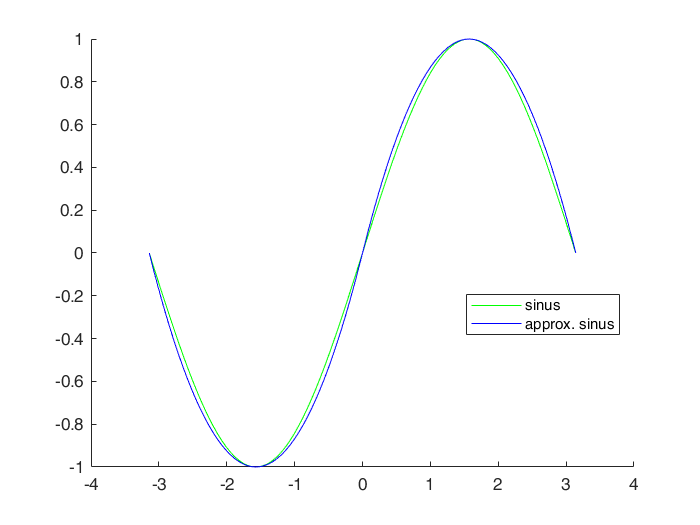

%solve (z_soll -(Z- c + sin(A)*(Y + Y_shift) + h_WZ*sin(A)) == B*fZ_WZrad  + r_WZ*cos(A)*(sin(B + phi_WZ)) , B )

%solve (k3 == B*fZ_WZrad  + r_WZ*cos(A)*(sin(B + phi_WZ)) , B )
%solve (k3 == B*fZ_WZrad  + r_WZ*cos(A)*(k1*(B + phi_WZ) - sign(B + phi_WZ)*k2*(B + phi_WZ)^2),B)
solve (k3 == B*fZ_WZrad  + r_WZ*cos(A)*(k1*(B + phi_WZ) - k2*(B + phi_WZ)^2),B)
solve (k3 == B*fZ_WZrad  + r_WZ*cos(A)*(k1*(B + phi_WZ) + k2*(B + phi_WZ)^2),B)

Transformationsmatrix der Maschine ohne Werkstücktransformation

TM_masch = T_XZ * R_A * T_Ys * R_B

$$ans = \begin{array}{l} \left(\begin{array}{c} \frac{9007199254740992\,{\mathrm{fZ}}_{\mathrm{WZrad}}-\sigma_{1}+11468322235794764\,r_{\mathrm{WZ}}\,\cos\left(A\right)-7300960726099801\,\varphi_{\mathrm{WZ}}\,r_{\mathrm{WZ}}\,\cos\left(A\right)}{7300960726099801\,r_{\mathrm{WZ}}\,\cos\left(A\right)}\\ \frac{9007199254740992\,{\mathrm{fZ}}_{\mathrm{WZrad}}+\sigma_{1}+11468322235794764\,r_{\mathrm{WZ}}\,\cos\left(A\right)-7300960726099801\,\varphi_{\mathrm{WZ}}\,r_{\mathrm{WZ}}\,\cos\left(A\right)}{7300960726099801\,r_{\mathrm{WZ}}\,\cos\left(A\right)} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=9007199254740992\,\sqrt{\frac{8220150931501538408199170613481\,{r_{\mathrm{WZ}}}^{2}\,{\cos\left(A\right)}^{2}}{5070602400912917605986812821504}+{{\mathrm{fZ}}_{\mathrm{WZrad}}}^{2}+\frac{2867080558948691\,{\mathrm{fZ}}_{\mathrm{WZrad}}\,r_{\mathrm{WZ}}\,\cos\left(A\right)}{1125899906842624}-\frac{7300960726099801\,k_{3}\,r_{\mathrm{WZ}}\,\cos\left(A\right)}{4503599627370496}-\frac{7300960726099801\,{\mathrm{fZ}}_{\mathrm{WZrad}}\,\varphi_{\mathrm{WZ}}\,r_{\mathrm{WZ}}\,\cos\left(A\right)}{4503599627370496}} \end{array}$$

Maschinentransformationsmatrix mal zylindrische Werkzeugkoordinaten

TM_masch * WZ_zyl

$$ans = \begin{array}{l} \left(\begin{array}{c} -\frac{9007199254740992\,{\mathrm{fZ}}_{\mathrm{WZrad}}-\sigma_{1}+11468322235794764\,r_{\mathrm{WZ}}\,\cos\left(A\right)+7300960726099801\,\varphi_{\mathrm{WZ}}\,r_{\mathrm{WZ}}\,\cos\left(A\right)}{7300960726099801\,r_{\mathrm{WZ}}\,\cos\left(A\right)}\\ -\frac{9007199254740992\,{\mathrm{fZ}}_{\mathrm{WZrad}}+\sigma_{1}+11468322235794764\,r_{\mathrm{WZ}}\,\cos\left(A\right)+7300960726099801\,\varphi_{\mathrm{WZ}}\,r_{\mathrm{WZ}}\,\cos\left(A\right)}{7300960726099801\,r_{\mathrm{WZ}}\,\cos\left(A\right)} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=9007199254740992\,\sqrt{\frac{8220150931501538408199170613481\,{r_{\mathrm{WZ}}}^{2}\,{\cos\left(A\right)}^{2}}{5070602400912917605986812821504}+{{\mathrm{fZ}}_{\mathrm{WZrad}}}^{2}+\frac{2867080558948691\,{\mathrm{fZ}}_{\mathrm{WZrad}}\,r_{\mathrm{WZ}}\,\cos\left(A\right)}{1125899906842624}+\frac{7300960726099801\,k_{3}\,r_{\mathrm{WZ}}\,\cos\left(A\right)}{4503599627370496}+\frac{7300960726099801\,{\mathrm{fZ}}_{\mathrm{WZrad}}\,\varphi_{\mathrm{WZ}}\,r_{\mathrm{WZ}}\,\cos\left(A\right)}{4503599627370496}} \end{array}$$

auskommentierte Lösung zum Vergleich

% [T_XZ * R_A * T_Ys * R_B] * [r_WZ*cos(phi_WZ);h_WZ;r_WZ*sin(phi_WZ);1]
%                                                                  X - a + B*fX_WZrad + r_WZ*cos(B)*cos(phi_WZ) - r_WZ*sin(B)*sin(phi_WZ)

$$TM\_masch = \begin{array}{l} \left(\begin{array}{cccc} \cos\left(B\right) & 0 & -\sin\left(B\right) & X-a+B\,{\mathrm{fX}}_{\mathrm{WZrad}}\\ -\sin\left(A\right)\,\sin\left(B\right) & \cos\left(A\right) & -\cos\left(B\right)\,\sin\left(A\right) & \cos\left(A\right)\,\sigma_{1}-b\\ \cos\left(A\right)\,\sin\left(B\right) & \sin\left(A\right) & \cos\left(A\right)\,\cos\left(B\right) & Z-c+B\,{\mathrm{fZ}}_{\mathrm{WZrad}}+\sin\left(A\right)\,\sigma_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=Y+Y_{\mathrm{shift}}+B\,{\mathrm{fY}}_{\mathrm{WZrad}} \end{array}$$

%                   cos(A)*(Y + Y_shift + B*fY_WZrad) - b + h_WZ*cos(A) - r_WZ*cos(B)*sin(A)*sin(phi_WZ) - r_WZ*sin(A)*sin(B)*cos(phi_WZ)
%  Z - c + B*fZ_WZrad + sin(A)*(Y + Y_shift + B*fY_WZrad) + h_WZ*sin(A) + r_WZ*cos(A)*cos(B)*sin(phi_WZ) + r_WZ*cos(A)*sin(B)*cos(phi_WZ)

$$ans = \begin{array}{l} \left(\begin{array}{c} X-a+B\,{\mathrm{fX}}_{\mathrm{WZrad}}+r_{\mathrm{WZ}}\,\cos\left(B\right)\,\cos\left(\varphi_{\mathrm{WZ}}\right)-r_{\mathrm{WZ}}\,\sin\left(B\right)\,\sin\left(\varphi_{\mathrm{WZ}}\right)\\ \cos\left(A\right)\,\sigma_{1}-b+h_{\mathrm{WZ}}\,\cos\left(A\right)-r_{\mathrm{WZ}}\,\cos\left(B\right)\,\sin\left(A\right)\,\sin\left(\varphi_{\mathrm{WZ}}\right)-r_{\mathrm{WZ}}\,\sin\left(A\right)\,\sin\left(B\right)\,\cos\left(\varphi_{\mathrm{WZ}}\right)\\ Z-c+B\,{\mathrm{fZ}}_{\mathrm{WZrad}}+\sin\left(A\right)\,\sigma_{1}+h_{\mathrm{WZ}}\,\sin\left(A\right)+r_{\mathrm{WZ}}\,\cos\left(A\right)\,\cos\left(B\right)\,\sin\left(\varphi_{\mathrm{WZ}}\right)+r_{\mathrm{WZ}}\,\cos\left(A\right)\,\sin\left(B\right)\,\cos\left(\varphi_{\mathrm{WZ}}\right)\\ 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=Y+Y_{\mathrm{shift}}+B\,{\mathrm{fY}}_{\mathrm{WZrad}} \end{array}$$

Lösung von ?

syms B_1
solve(Z - c + B_1*fZ_WZrad + sin(A)*(Y + Y_shift + B_1*fY_WZrad) + h_WZ*sin(A) + cos(A)*r_WZ.*sin(B-phi_WZ)==z_soll, B)

$$ans = \left(\begin{array}{c} \varphi_{\mathrm{WZ}}-\mathrm{asin}\left(\frac{Z-c-z_{\mathrm{soll}}+B_{1}\,{\mathrm{fZ}}_{\mathrm{WZrad}}+\sin\left(A\right)\,\left(Y+Y_{\mathrm{shift}}+B_{1}\,{\mathrm{fY}}_{\mathrm{WZrad}}\right)+h_{\mathrm{WZ}}\,\sin\left(A\right)}{r_{\mathrm{WZ}}\,\cos\left(A\right)}\right)\\ \varphi_{\mathrm{WZ}}+\pi +\mathrm{asin}\left(\frac{Z-c-z_{\mathrm{soll}}+B_{1}\,{\mathrm{fZ}}_{\mathrm{WZrad}}+\sin\left(A\right)\,\left(Y+Y_{\mathrm{shift}}+B_{1}\,{\mathrm{fY}}_{\mathrm{WZrad}}\right)+h_{\mathrm{WZ}}\,\sin\left(A\right)}{r_{\mathrm{WZ}}\,\cos\left(A\right)}\right) \end{array}\right)$$

%      phi_WZ - asin((Z - c - z_soll + B_1*fZ_WZrad + sin(A)*(Y + Y_shift + B_1*fY_WZrad) + h_WZ*sin(A))/(r_WZ*cos(A)))
% phi_WZ + pi + asin((Z - c - z_soll + B_1*fZ_WZrad + sin(A)*(Y + Y_shift + B_1*fY_WZrad) + h_WZ*sin(A))/(r_WZ*cos(A)))
